clear; clc;
w0 = 0.3*pi;
M = 16;
n = 0:M-1;
syms w
x = cos(w0.*n);

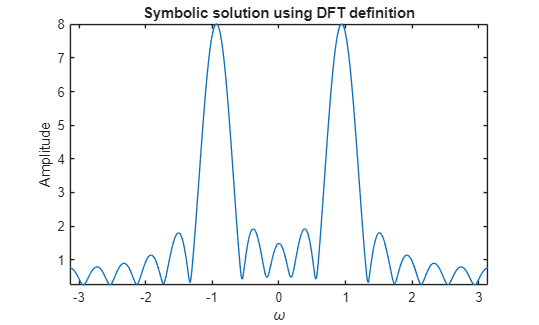

% solve symbolically
X = sum(x(n+1).*exp(-1j.*w.*n));
fplot(abs(X), [-pi pi])
xlabel('\omega'); ylabel('Amplitude'); title('Symbolic solution using DFT definition');

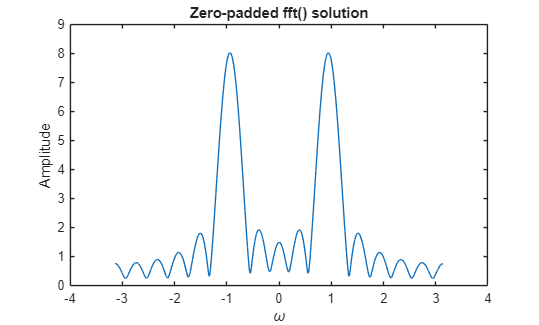

% mucho zero padding
N = 4096;
X = fft(x, N);
plot(linspace(-pi,pi, N), abs(fftshift(X)))
xlabel('\omega'); ylabel('Amplitude'); title('Zero-padded fft() solution');


[mag, idx] = max(abs(X));
Mainlobe_height = mag

Mainlobe_height = 8.0083


min_inds = find(islocalmin(abs(X)));
right = min_inds(min_inds > idx);
left = min_inds(min_inds < idx);
Mainlobe_Width = 2*pi/N*(right(1) - left(end))

Mainlobe_Width = 0.7823


[pks, ~] = findpeaks(abs(X));
pks = sort(pks,"descend");
Sidelobe_height = pks(3)

Sidelobe_height = 1.9149

Sidelobe_dB = 20*log10(Sidelobe_height/Mainlobe_height)

Sidelobe_dB = -12.4278

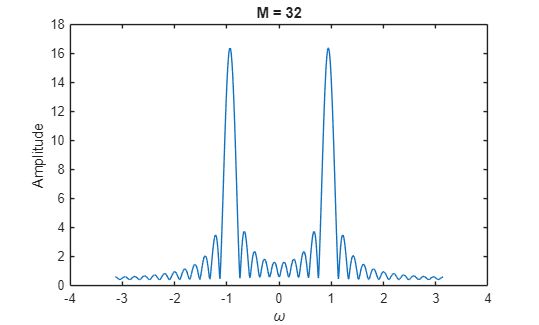

% Double M
M = 2 * M;
n = 0:M-1;
x = cos(w0.*n);

X = fft(x, N);
plot(linspace(-pi,pi, N), abs(fftshift(X)))
xlabel('\omega'); ylabel('Amplitude'); title("M = " + num2str(M));


[mag, idx] = max(abs(X));
Mainlobe_height = mag

Mainlobe_height = 16.3534


min_inds = find(islocalmin(abs(X)));
right = min_inds(min_inds > idx);
left = min_inds(min_inds < idx);
Mainlobe_Width = 2*pi/N*(right(1) - left(end))

Mainlobe_Width = 0.3850


[pks, ~] = findpeaks(abs(X));
pks = sort(pks,"descend");
Sidelobe_height = pks(3)

Sidelobe_height = 3.7248

Sidelobe_dB = 20*log10(Sidelobe_height/Mainlobe_height)

Sidelobe_dB = -12.8500

The main lobe is approximately half as wide and twice as tall. The sidelobe doubled in height as well, so the dB value remains fairly similar.

It looks like a larger M (larger window, larger number of samples) results in a better DFT.